# Structural Econometrics Assignment 3 - Auction Estimation

This assignment will guide you through the main estimation steps of the dynamic auction model of "Bidding Frictions in Ascending Auctions" to give an idea of the techniques involved in each step. 

To begin, recall that the auction model used has the following features:

- Valuations for each bidder $i$ at auction $j$ are given by $v_{\left\lbrace \textrm{ij}\right\rbrace } =y_j {\;x}_i +\underline{r}$ $\forall \ i \in \mathcal{I}$, where $y$ is the auction-specific component common to all bidders, $x_i$ is bidder $i$'s private valuation component, and $\underline{r}$ is the auction reserve price.

- Bids can be placed at any moment over a time interval $[0, \mathcal{T}]$, where $\mathcal{T}$ is the end time of the auction.

- Bidding opportunities are random and generated according to the following process: when a bid by bidder $i$ is currently winning (in-the-money or INM), no new bidding opportunties for bidder $i$ will arise. If bidder $i$'s bid is supplanted by another bid so that it is no longer a provisionally winning bid (out-of-the-money or OUTM), a random process will determine when the next bidding opportunity is for that bidder. Specifically, if bidder $i$'s bid is pushed OUTM at time $t$, then the next time $\tau$ for that bidder to bid is a random variable that has cdf $G_{\tau}(t)$. Note that this distribution depends on the time pushed OUTM $t$; this means that the frequency of bidding opportunities may change over the auction's duration.

- Bidders always place a bid whenever they have an opportunity to do so, provided that the minimum bid required to be INM does not exceed their valuation.

- The lowest provisionally winning bid at any moment in the auction is referred to as the ONM rate.

With these pieces in place, we can describe the estimation of the model in three steps:

- Estimate the arrival times of new bidding opportunities conditional on being pushed OUTM at time $t$. Because we observe when all bids were placed, this is directly identified from the data and can be done with readily available methods.

- Use the distribution of bids to estimate the (joint) distribution of (pairs of) valuations within an auction.This is the "hard part" as it requires construction of a likelihood function over pairs of bids as a function of the joint distribution of valuation pairs. This gives the distribution of $(V_1, V_2)$, or the joint distribution of a pair of valuations within an auction

- Use deconvolution to separate  the distributions of $X$ and $Y$. This uses known methods but involves some messy numerical integration.

## 1. Estimating the distribution of bidding arrival times

There are two main data files: response_times_data contains a random subset of bid times, and pre_est_data has more complete bidding data. For now we can load only the response times:

load response_times_data.mat

 Each column corresponds to a single bid, where each row has a value for "response_time", or the time that a new bid was placed, and "cross_time", which is the time that the bidder's previous bid was pushed OUTM. 

responses(1:10,:)

ans = 10×2 table
    response_time    cross_times
    _____________    ___________

        1729            1653    
        1086            1062    
        1776            1763    
        1214            1196    
        1418            1394    
        1788            1788    
        1627            1609    
        1762            1751    
        1771            1757    
         590             546    


The first entry corresponds to a bidder that submitted a bid at 1729 seconds into the auction (at about minute 29) after being pushed OUTM at 1653 seconds (27.5 minutes). 

We are primarily interested in the time elapsed between bids, which is "reponse_time" minus "cross_time". If we just want the raw, unconditional cdf we can use built-in Matlab commands

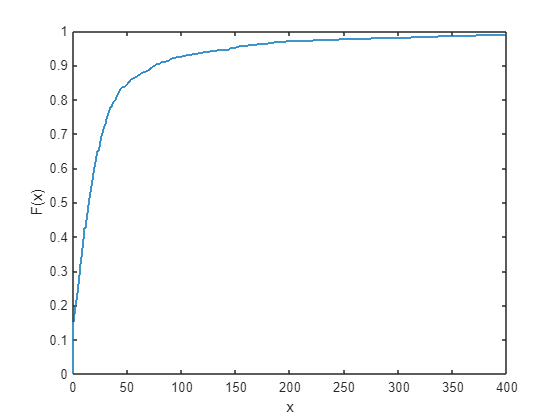

ecdf(responses.response_time - responses.cross_times)
xlim([0,400])

However, we want the distribution of bidding opportunity arrivals conditional on the time that a bidder is pushed OUTM. 

#### Exercise 1: Use the formula in Section 5.1 of the paper to estimate the CDF of bidding arrival times when $t=10$ and when $t=25$. Graph the CDFs you obtain.

Recall that the formula is 


$$\widehat{G}_{t}(z)=\frac{\sum_{n=1}^{N}\sum_{j=0}^{J_{n}-1}K\left( \frac{%
\tau _{nj}-t}{h}\right) 1\{\rho _{n,j+1}-\tau _{nj}<z\}}{%
\sum_{n=1}^{N}\sum_{j=1}^{J_{n}}K\left( \frac{\tau _{nj}-t}{h}\right) }$$


where $\tau_{nj}$ is the time that the previous bid $j$ was pushed OUTM and $\rho_{n,j+1}$ is the time of the next bid $j+1$. While there are two summations in the formula, you can use a single sum over all the data points in the "responses" table. Use a Gaussian kernel with bandwidth parameter $h$ chosen using Silverman's rule of thumb.

% Exercise 1 code and output here



## 2. Estimating the distribution of valuations

 load pre_est_data.mat

#### Winning bids

The second data file contains the data relevant to estimating the distribution of valuations $F_V(\cdot)$. There are two arrays that contain bid data: "winning_bid_data" contains bids that won the auction, while "last" is a cell that contains information on bids that did not win the auction but were the last bid placed by a bidder in a given auction.

All bids have been assigned to a value on a discrete grid that goes from 0 to 1. These gridpoints are contained in the file "value_grid". *Note: for the purpose of this assignment, the grid is only 10 points.*

winning_bid_data(780:785)

  Each entry in "winning_bid_data" references an index in "value_grid". If we want the bid values, instead of the indices, we plug them into the value_grid array:

value_grid(winning_bid_data(780:785))

#### Losing bids

The last bid placed by any losing bidder $i$ is contained in "last". Because the last bid is the highest bid placed by bidder $i$, it contains the most information about that bidder's valuation. Each entry in this cell is an array that documents each increase to the ONM rate *after *the last bid of bidder $i$ has been pushed OUTM. We need to document each ONM rate increase as there are two things that can occur during each increase and they have different implications for bidder $i$'s valuation. Suppose that the ONM rate increase from $r_{t}$ at time $t$ to $\tilde{r}_{\tau}$ at time $\tau$. Two things might have happened:   

- Bidder $i$ received an opportunity to bid in the interval $[t, \tau]$, but bidder $i$'s valuation was below $r_t$.

- Bidder $i$ never received an opportunity to bid (and her valuation may or may not have been below $r_t$).

Because we have already estimated the probability of receiving a bidding opportunity in Part 1, we can assign probabilities to each of these events and construct a likelihood function in terms of only bidder $i$'s valuation.

The cell "last" has 5 columns, but only three are useful for the purposes of this assignment. Ignore columns 1 and 2 in in estimation.

Column 3: the value grid index corresponding to the time t ONM rate.

Column 4: the value grid index corresponding to the time t-1 ONM rate.

Column 5: the CDF of the arrival rate distribution that gives the probability that a bid will have been received by the time of the ONM rate increase, starting from the time the last bid was pushed OUT. That is, this column is $G_{\tau}(t)$, where $\tau$ is the time the bidder's final bid was pushed OUT and $t$ is the time of the ONM rate increase.

#### Bid locations

Bid locations gives the indices of the sampled bid pairs used in the estimation. Columns 1 and 2 correspond to the first bid in the pair. Columns 3 and 4 correspond to the second bid in the pair. If column 1 is greater than zero, then that bid was a winning bid and column 1 gives the index of the winning bid in the winning_bid_data variable. Otherwise, if column 2 is greater than zero than the bid was not winning and the column gives the index of the losing bid data in the last variable.

The same holds for columns 3 and 4: column 3 corresponds to winning bids for the second bid in the pair, and column 4 corresponds to losing bids for the second bid in the pair.

Estimation proceeds by splitting the "bid_locations" variable into the cases described in the appendix and constructing the likelihood for each case. Note that the variable read into the likelihood function is a 100x1 vector; to work with the CDF in matrix form within the likelihood you should first reshape this vector into a matrix and take its transpose, e.g. "F=reshape(F_v,[10,10])';"

Finally, there are two additional files: starting_guess, which contains an initial point for the optimizer, and constraint_conditions. The optimization imposes constraints on the solution, specifically that we need the solution to be a valid joint CDF (weakly increasing, values between zero and one, etc.). The constraint conditions file gives the variables needed by the optimizer to impose these conditions in estimation when using the "fmincon" function.

***IMPORTANT: ***make sure you have the most recent version of Matlab installed, as the optimizer uses the "EnableFeasibilityMode" option which may not be available on previous releases. If you can't use this mode you can delete this section of code in the optimizer call below, but be warned that you may converge to an infeasible point!

#### Exercise 2: When sampling pairs of bids from the set of all bids, we categorize each pair into the four possible outcomes, explained in appendix C.2: both bids are winning bids, the first wins while the second loses, the first loses while the second wins, or both bids lose. The likelihood function, "joint_likelihood" contained at the end of this document, separately calculates these four components. Complete the likelihood function by filling in the missing entries for the first and third components, corresponding to the “win-win” case and the “lose-win” case, respectively. Estimate the joint distribution, and visualize the output as a shaded grid using Matlab's built-in "heatmap" command.

% Excercise 2 code and output here
load constraint_conditions.mat % loads the constraints used in the optimization routine
load starting_guess.mat % loads the starting guess used for the optimizer (a randomly sampled independent uniform joint distribution)

N_value=10;
v_grid=value_grid';

likelihood_fun=@(F)joint_likelihood(F,winning_bid_data,last,bid_locations);

options=optimoptions('fmincon','Display','iter','TolCon',1e-6,'TolX',1e-6,'MaxFunEvals',60000,'ConstraintTolerance',1e-6,'EnableFeasibilityMode',true,'SubproblemAlgorithm','cg');
F_v=fmincon(likelihood_fun,F0,constraint_matrix,b,Aeq,beq,lb,[],[],options);

heatmap(reshape(F_v,[10,10]))

## 3. Deconvolution

The last component of the estimation is using the deconvolution techniques of Kotlarski (1966) and applied to economics by Li and Vuong (1998), and Krasnokutskaya (2011). The basic idea of deconvolution is to use the joint distribution of pairs of observations to recover the underlying random processes that govern the joint distribution. More concretely, suppose we have a two random variables $Z_1,Z_2$, with


$$\begin{array}{l}
Z_1 =Y+X_1 ,\;\;\;\\
Z_2 =Y+X_2 \ldotp 
\end{array}$$


Assume further that $X_1$, $X_2$, and $Y$ are mutually independent. Clearly $Z_1$ and $Z_2$ are not independent variables, as they are correlated by the realization of $Y$. Kotlarski (1966) showed that the distributions of $X_1$, $X_2$, and $Y$ are uniquely determined by the joint distribution of $Z_1,Z_2$ up to the location of $Y$ (that is, we have to fix the mean of $Y$in estimation). *Note: we can also apply these techniques in the exact same way if there is a multiplicative structure *$Z_i = YX_i$ *by taking logs.*

Specifically, with the characteristic function of $(\ln(V_1),\ln(V_2))$, $\phi_{V_1,V_2}(t_1,t_2)$, we can recover the characteristic functions of $\ln(Y)$ and $\ln(X)
$, $\phi_{\ln(X)}(t)$ and $\phi_{\ln(Y)}
(t)$ as


$$
\hat{\phi}_{\ln Y}(t) = \exp \left( \int_{0}^{t}\frac{\partial }{\partial u}
\left[ \frac{\hat{\phi}_{\ln V_{1},\ln V_{2}}(u,v)}{\hat{\phi}_{\ln V_{1},\ln V_{2}}(u,0)%
\hat{\phi}_{\ln V_{1},\ln V_{2}}(0,v)}\right] _{u=0}dv\right) 
$$



$$\hat{\phi}_{\ln X}(t) =\frac{\hat{\phi}_{\ln V_{1},\ln V_{2}}(t,0)}{\hat{\phi}_{\ln Y}(t)}
$$


We can recover the pdf of these random variables from the characteristic functions using the inverse Fourier transform:


$$\hat{p}_{\ln Y}(y) =\frac{1}{2\pi }\int_{-T}^{T}e^{ity}\hat{\phi}_{\ln Y}(t)dt$$


These techniques are useful for auctions as they allow for the introduction of *unobserved auction heterogeneity*: we typically assume that bidders' valuations are independent within an auction, possibly after controlling for a set of observable covariates. However, if there are relevant covariates that are *unobserved* to the econometrician, this assumption will be violated: valuations will not be independent due to the correlation induced by this unobserved factor. Deconvolution approaches allow for the econometrician to control for the presence of these factors, and was pioneered in this context by Krasnokutskaya (2011).

Deconvolution approaches are also useful in other contexts, especially the measurement error literature. Suppose we have two realizations of wages, $W_1$ and $W_2$, but both come from data sets of poor quality and there are concerns about measurement error in wages influencing regression results. If we fix average wages (that is, we set $E[Y] = \overline{w}$, where $\overline{w}$ comes from more accurate aggregate statistics), then we can estimate and control for the measurement error components $X_1$ and $X_2$ using deconvolution. Li and Vuong (1998) first applied these techniques in econometrics, and Schennach (2004 Econometrica) provides a more comprehensive treatment.

For our purposes, we are going to use a toy data set to demonstrate how deconvolution works. First we load the last data set, which contains realizations from a joint distribution of (continuous) random variables $z_1,z_2$. 

load deconv_data

$z_1,z_2$ come from a distribution generated by $(Z_1, Z_2) = (Y X_1, YX_2)$ for $Y, X$ mutually independent and $X_1, X_2 \sim F(\cdot)$, with $z_i \equiv \log(Z_i)$. (Note: the X's are i.i.d and follow the same distribution).

#### Exercise 3: evaluate the deconvolution method using the code below and graph the results you obtain. Next, perform the change of variables to "un-logarithm" the resulting random variables, and plot the results as a cdf instead of a pdf.

[y,x,Y_grid,X_grid]=deconvolution(v) % This takes inputs v, an Nx2 vector, and outputs y, which is the pdf of Y, and x, which is the pdf of X.
% Each pdf is evaluated at a set of grid points, defined by Y_grid and
% X_grid.


## Appendix: Functions

Joint likelihood:

function [lik]=joint_likelihood(F_v,winning_bids,last,bid_locations)

% F is read in as a 100x1 vector: reshape to 10x10 matrix
F=reshape(F_v,[10,10])';

% Break into cases

% Win-win
win_win_locs=bid_locations(bid_locations(:,1)>0 & bid_locations(:,3)>0,[1,3]);

% Define L1: the component of the likelihood for pairs of bids that are
% both winning.

% Win-lose

win_lose_locs=bid_locations(bid_locations(:,1)>0 & bid_locations(:,4)>0,[1,4]);
L2=zeros(size(win_lose_locs,1),1);
for j=1:size(win_lose_locs,1)
    L2(j)=sum((F(end,last{win_lose_locs(j,2),1}(:,3))-F(winning_bids(win_lose_locs(j,1)),last{win_lose_locs(j,2),1}(:,3))).*(1-last{win_lose_locs(j,2),1}(:,5))')... 
        +(1-(F(winning_bids(win_lose_locs(j,1)),end)+(F(end,last{win_lose_locs(j,2),1}(1,4))-F(winning_bids(win_lose_locs(j,1)),last{win_lose_locs(j,2),1}(1,4)))))*(1-last{win_lose_locs(j,2),1}(end,5)); % Defines "rectangle" of valuations grid
end


% Lose-win: same as above with roles reversed
lose_win_locs=bid_locations(bid_locations(:,2)>0 & bid_locations(:,3)>0,[2,3]);
lose_win_locs=[lose_win_locs(:,2),lose_win_locs(:,1)];

% Define L3: the component of the likelihood for pairs of bids that have
% one losing bid and one winning bid. Hint: you may find the L2 definition
% helpful



% Lose-Lose
lose_lose_locs=bid_locations(bid_locations(:,2)>0 & bid_locations(:,4)>0,[2,4]);
L4=zeros(size(lose_lose_locs,1),1);
for j=1:size(lose_lose_locs,1)
    temp_F=(F(last{lose_lose_locs(j,1),1}(:,3),last{lose_lose_locs(j,2),1}(:,3))-F(last{lose_lose_locs(j,1),1}(:,4),last{lose_lose_locs(j,2),1}(:,3)))...
        -(F(last{lose_lose_locs(j,1),1}(:,3),last{lose_lose_locs(j,2),1}(:,4))-F(last{lose_lose_locs(j,1),1}(:,4),last{lose_lose_locs(j,2),1}(:,4)));
    
    L4(j)=(1-(F(last{lose_lose_locs(j,1),1}(end,4),end)+(F(end,last{lose_lose_locs(j,2),1}(1,4))-F(last{lose_lose_locs(j,1),1}(end,4),last{lose_lose_locs(j,2),1}(1,4)))))*(1-last{lose_lose_locs(j,2),1}(end,5))*(1-last{lose_lose_locs(j,1),1}(end,5))...
        +(1-last{lose_lose_locs(j,2),1}(end,5))*sum((F(last{lose_lose_locs(j,1)}(:,3),end)-F(last{lose_lose_locs(j,1)}(:,4),end))-(F(last{lose_lose_locs(j,1)}(:,4),last{lose_lose_locs(j,2)}(end,3))-F(last{lose_lose_locs(j,1)}(:,4),last{lose_lose_locs(j,2)}(end,4))).*(1-last{lose_lose_locs(j,1)}(:,5)))...
        +(1-last{lose_lose_locs(j,1),1}(end,5))*sum((F(end,last{lose_lose_locs(j,2)}(:,3))-F(end,last{lose_lose_locs(j,2)}(:,4)))-(F(last{lose_lose_locs(j,1)}(end,3),last{lose_lose_locs(j,2)}(:,4))-F(last{lose_lose_locs(j,1)}(end,4),last{lose_lose_locs(j,2)}(:,4))).*(1-last{lose_lose_locs(j,2)}(:,5))')... 
        +(1-last{lose_lose_locs(j,1),1}(:,5))'*temp_F*(1-last{lose_lose_locs(j,2),1}(:,5));
end
L4(L4<=0)=[];


lik=(-1)*(sum(log(L1))+sum(log(L2))+sum(log(L3))+sum(log(L4)));
end

Deconvolution:

function [y,z,Y_grid,Z_grid]=deconvolution(Z)

Y_grid=linspace(-4,0,20);
Z_grid=linspace(-1.5,2.5,20);
Y_pdf=zeros(size(Y_grid,2),1);
Z_pdf=zeros(size(Z_grid,2),1);

T=3;
T2=10;


fun1=@(U) arrayfun(@(u) exp(integral(@(t1) psi1_psi(t1,Z),0,u)),U);

fun2=@(U) arrayfun(@(u) characteristic_function(u,0,Z)./(exp(integral(@(t1) psi1_psi(t1,Z),0,u))),U);
% Dampening factor:(1-(abs(t)/T2)).*
for j=1:size(Y_grid,2)
    Y_pdf(j)=(1/(2*pi))*integral(@(t) (1-(abs(t)/T)).*exp(-1i.*t.*Y_grid(j)).*fun1(t),-T,T);
    Z_pdf(j)=(1/(2*pi))*integral(@(t) (1-(abs(t)/T2)).*exp(-1i.*t.*Z_grid(j)).*fun2(t),-T2,T2);
end
Y_pdf=real(Y_pdf);
Y_mean=trapz(Y_grid,Y_grid'.*Y_pdf);


y=Y_pdf;
z=real(Z_pdf);

end

function char=characteristic_function(t1,t2,Z)
char=mean(exp(1i.*t1.*Z(:,1) + 1i.*t2.*Z(:,2)));
end

function ratio=psi1_psi(t1,Z)
ratio=((characteristic_function(1e-2,t1,Z)-characteristic_function(-1e-2,t1,Z))./2e-2)./characteristic_function(0,t1,Z);
end